clc
clear all

syms theta1 theta2 theta3 theta4

thetasi=[theta1 theta2 theta3 theta4]';
di=[4 0 0 0]';
ai=[0 10.5 10.5 9]';
alphai=[pi/2 0 0 0]';
offset=[0 pi/2 pi/2 0]';
DH=[thetasi di ai alphai offset];

%tramsformadas
T01=trotz(DH(1,1))*transl(0,0,DH(1,2))*transl(DH(1,3),0,0)*trotx(DH(1,4))

$$T01 = \left(\begin{array}{cccc} \cos\left(\bar{\theta_{1}}\right) & 0 & \sin\left(\bar{\theta_{1}}\right) & 0\\ \sin\left(\bar{\theta_{1}}\right) & 0 & -\cos\left(\bar{\theta_{1}}\right) & 0\\ 0 & 1 & 0 & 4\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12=trotz(DH(2,1))*transl(0,0,DH(2,2))*transl(DH(2,3),0,0)*trotx(DH(2,4))

$$T12 = \left(\begin{array}{cccc} \cos\left(\bar{\theta_{2}}\right) & -\sin\left(\bar{\theta_{2}}\right) & 0 & \frac{21\,\cos\left(\bar{\theta_{2}}\right)}{2}\\ \sin\left(\bar{\theta_{2}}\right) & \cos\left(\bar{\theta_{2}}\right) & 0 & \frac{21\,\sin\left(\bar{\theta_{2}}\right)}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23=trotz(DH(3,1))*transl(0,0,DH(3,2))*transl(DH(3,3),0,0)*trotx(DH(3,4))

$$T23 = \left(\begin{array}{cccc} \cos\left(\bar{\theta_{3}}\right) & -\sin\left(\bar{\theta_{3}}\right) & 0 & \frac{21\,\cos\left(\bar{\theta_{3}}\right)}{2}\\ \sin\left(\bar{\theta_{3}}\right) & \cos\left(\bar{\theta_{3}}\right) & 0 & \frac{21\,\sin\left(\bar{\theta_{3}}\right)}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34=trotz(DH(4,1))*transl(0,0,DH(4,2))*transl(DH(4,3),0,0)*trotx(DH(4,4))

$$T34 = \left(\begin{array}{cccc} \cos\left(\bar{\theta_{4}}\right) & -\sin\left(\bar{\theta_{4}}\right) & 0 & 9\,\cos\left(\bar{\theta_{4}}\right)\\ \sin\left(\bar{\theta_{4}}\right) & \cos\left(\bar{\theta_{4}}\right) & 0 & 9\,\sin\left(\bar{\theta_{4}}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


TCP=[0 0 1 1;
      0 1 0 0;
      1 0 0 0;
      0 0 0 1]

TCP =      0     0     1     1
     0     1     0     0
     1     0     0     0
     0     0     0     1



T0tcp=T01*T12*T23*T34*TCP


%         [theta,d,a,alpha,sigmamHD,Offset]
L1 = Link('revolute','d',4 ,'a',0,'alpha',pi/2,"offset",0);
L2 = Link('revolute','d',0 ,'a',10.5,'alpha',0,"offset",pi/2);
L3 = Link('revolute','d',0 ,'a',10.5,'alpha',0,"offset",0);
L4 = Link('revolute','d',0 ,'a',9,'alpha',0,"offset",0);


%L33;L43;L53;L63
Links=[L1;L2;L3;L4];
Robot= SerialLink(Links);
W=[-15 15 -15 15 -15 15];
Robot.name="Robot1-1"

 
Robot = 
 
Robot1-1:: 4 axis, RRRR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|     1.5708|          0|
|  2|         q2|          0|       10.5|          0|     1.5708|
|  3|         q3|          0|       10.5|          0|          0|
|  4|         q4|          0|          9|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



%configuracion herramienta
%Robot.tool=TCP;
Rtool= eye(4)*transl([1 0 0])

Rtool =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


Rtool=[1 0 0 0;
      0 1 0 0;
      0 0 1 0;
      0 0 0 1]

Rtool =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



%con los valores de q igual a 0
Robot.name="PoseHome"

 
Robot = 
 
PoseHome:: 4 axis, RRRR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|     1.5708|          0|
|  2|         q2|          0|       10.5|          0|     1.5708|
|  3|         q3|          0|       10.5|          0|          0|
|  4|         q4|          0|          9|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


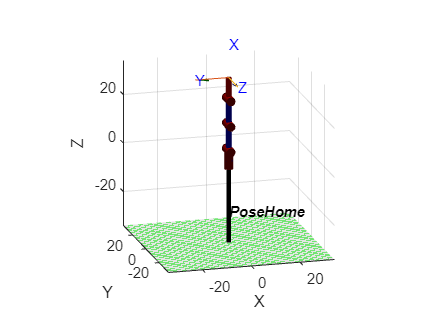

Robot.plot([0 0 0 0],"view",[-15.2 16.4])

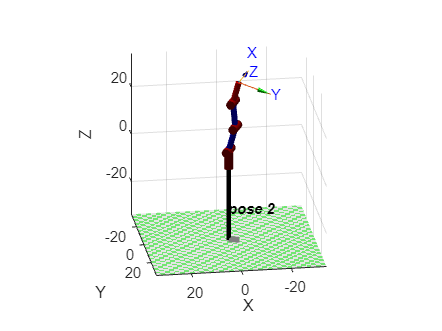

clf
Robot.name="pose 2";
Robot.plot([-25*pi/180 15*pi/180 -20*pi/180 20*pi/180],"view",[171.6 21.0])

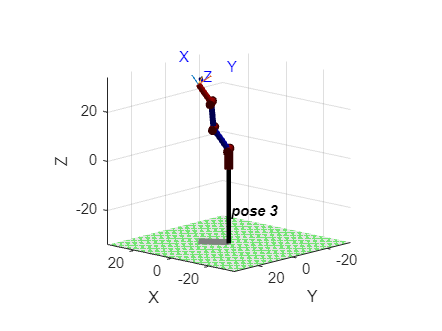

clf
Robot.name="pose 3";
Robot.plot([35*pi/180 -35*pi/180 30*pi/180 -30*pi/180],"view",[222.2 13.5])

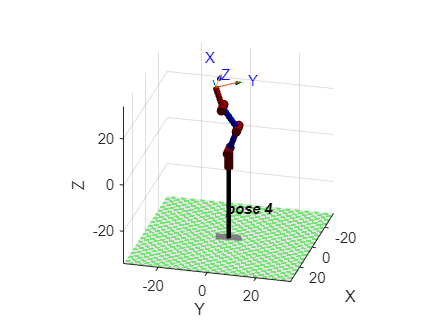

clf
Robot.name="pose 4";
Robot.plot([-85*pi/180 20*pi/180 -55*pi/180 17*pi/180],"view",[104.5 24.0])

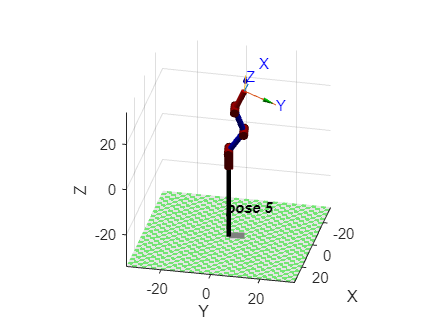

clf
Robot.name="pose 5";
Robot.plot([-80*pi/180 35*pi/180 -55*pi/180 45*pi/180],"view",[102.2 26.8])